% Coordenadas dos nós da ponte (em mm)
nodes = [
   31   0;    % 1
   78  28;    % 2
  156  56;    % 3
  234  84;    % 4
  312  84;    % 5
  390  56;    % 6
  468  28;    % 7
  515 0;      % 8
  78  0;      %9
  78 -39;     %10
  156 0;      %11
  234 25;     %12
  312 25;     %13
  390  0;     %14
  468 0;      %15
  468 -39;    %16
];


% Matriz de incidências de cada elemento
elementos = [
    1 2; 2 3; 3 4; 4 5; 5 6; 6 7; 7 8; %topo
    2 11; 3 9; 3 12; 4 11; 4 13; 5 12; 5 14; 6 13; 6 15; 7 14; %diagonais
    1 9; 9 11; 11 12; 12 13; 13 14; 14 15; 8 15; % base
    2 9; 3 11; 4 12; 5 13; 6 14; 7 15; % verticais
    9 10; 10 11; 14 16; 15 16; % suporte
];

num_elementos = size(elementos,1);
num_nos = size(nodes,1);


figure; hold on; axis equal;
for i = 1:size(elementos,1)
    n1 = elementos(i,1);
    n2 = elementos(i,2);
    plot([nodes(n1,1) nodes(n2,1)], [nodes(n1,2) nodes(n2,2)], 'k-', 'LineWidth', 2);
end

% Destacar as barras azuis (sugestão pela imagem)
blue_elementos = [ 3 9; 4 11; 5 14; 6 15];
for i = 1:size(blue_elementos,1)
    n1 = blue_elementos(i,1);
    n2 = blue_elementos(i,2);
    plot([nodes(n1,1) nodes(n2,1)], [nodes(n1,2) nodes(n2,2)], 'b-', 'LineWidth', 3);
end

% Plotar os nós
for i = 1:num_nos
    plot(nodes(i, 1), nodes(i, 2), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
    text(nodes(i, 1), nodes(i, 2), sprintf(' %d', i), 'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
xlabel('x (mm)'); ylabel('y (mm)');
title('Ponte Treliçada (barras de 100 mm)');
grid on;


% 1c. Propriedades dos elementos (todas iguais para simplificação)
A = 60 % área da seção (mm^2)

A = 60

E = 3300 %MPa

E = 3300

%considerando menor tensão
TR_tracao = 55 %  [8000] - 11000(76) MPa

TR_tracao = 55

TR_compressao = 76 % [11000] - 19000(131) MPa

TR_compressao = 76


% 1d. Numeração dos graus de liberdade
n_GL = num_nos * 2;

% 1e. Graus de liberdade restritos (apoios)
% Nós 1,9,10 e 8, 15, 16

fix_dofs = [8*2 - 1, 8*2, 9*2 - 1, 9*2, 15*2-1, 15*2, 1*2 - 1, 1*2, 10*2 - 1, 10*2, 16*2 - 1, 16*2];



%% PASSO 2: Montar a matriz de rigidez de CADA elemento
len_elementos = zeros(num_elementos,1);
cos_sen       = zeros(num_elementos,2);
K_elem        = cell(num_elementos,1);

for e = 1:num_elementos
    n1 = elementos(e,1);
    n2 = elementos(e,2);
    dx = nodes(n2,1)-nodes(n1,1);
    dy = nodes(n2,2)-nodes(n1,2);
    L  = hypot(dx,dy);
    len_elementos(e) = L;
    c = dx/L;  s = dy/L;
    cos_sen(e,:) = [c s];
    ke = (E*A/L)*[ c^2  c*s -c^2 -c*s;
                   c*s  s^2 -c*s -s^2;
                  -c^2 -c*s  c^2  c*s;
                  -c*s -s^2  c*s  s^2 ];
    K_elem{e} = ke;
end

%% PASSO 3: Montar a matriz de rigidez GLOBAL [Kg]
Kg = zeros(n_GL);
for e = 1:num_elementos
    n1 = elementos(e,1);
    n2 = elementos(e,2);
    dofs = [2*n1-1 2*n1 2*n2-1 2*n2];
    Kg(dofs,dofs) = Kg(dofs,dofs) + K_elem{e};
end

disp('==========================================')

Kg

Kg = 1.0e+04 *

    0.6884    0.1591   -0.2671   -0.1591         0         0         0         0         0         0         0         0         0         0         0         0   -0.4213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1591    0.0948   -0.1591   -0.0948         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2671   -0.1591    0.6904    0.1591   -0.2116   -0.0760         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.2116    0.0760         0         0         0         0         0         0         0         0         0         0
   -0.1591   -0.0948 


%% PASSO 4: Montar o vetor global de forças [Pg]
Pg = zeros(n_GL,1);
% f) cargas aplicadas: 150 N para baixo distribuídos nos nós 4 e 5
forca = 700

forca = 700

Pg(2*4) = -forca/2;  
Pg(2*5) = -forca/2;

disp('==========================================');

Pg

Pg =      0
     0
     0
     0
     0
     0
     0
  -350
     0
  -350



%% PASSO 5: Aplicar condições de contorno (eliminar linhas/colunas)
% e) 6 apoios do suporte:
%   nó 1 → ux,uy;  nó 9 → ux;  nó 10 → uy;
%   nó 8 → ux,uy;  nó 15 → ux;  nó 16 → uy
restricao = [ ...
    2*1-1, 2*1, ...   % nó 1: ux, uy
    2*9-1,       ...  % nó 2: ux
      2*10,      ...  % nó10: uy
    2*8-1, 2*8, ...   % nó 8: ux, uy
    2*15-1,       ...  % nó 7: ux
      2*16          % nó16: uy
];
restricao

restricao =      1     2    17    20    15    16    29    32



Kg_red = Kg;
Pg_red = Pg;
Kg_red(restricao,:) = [];
Kg_red(:,restricao) = [];
Pg_red(restricao)    = [];
disp("==========================================")

Kg_red

Kg_red = 1.0e+04 *

    0.6904    0.1591   -0.2116   -0.0760         0         0         0         0         0         0         0         0         0         0   -0.2116    0.0760         0         0         0         0         0         0         0         0
    0.1591    0.8565   -0.0760   -0.0273         0         0         0         0         0         0         0         0   -0.7071         0    0.0760   -0.0273         0         0         0         0         0         0         0         0
   -0.2116   -0.0760    0.7631    0.1687   -0.2116   -0.0760         0         0         0         0         0         0   -0.0977         0         0         0   -0.2037    0.0810         0         0         0         0         0         0
   -0.0760   -0.0273    0.1687    0.5104   -0.0760   -0.0273         0         0         0         0         0         0   -0.0701         0         0   -0.3536    0.0810   -0.0322         0         0         0         0         0         0
         0      

disp("==========================================")

Pg_red

Pg_red =      0
     0
     0
     0
     0
  -350
     0
  -350
     0
     0



%% PASSO 6: Resolver o sistema de equações
%    [Kg_red] * {U_red} = {Pg_red}
U = Kg_red \ Pg_red;
U_expandida = zeros(num_nos*2, 1);
for row = 1:length(restricao)
    i = restricao(row);
    U_expandida(i) = U(row);
end
disp("==========================================")

U_expandida

U_expandida =     0.0380
   -0.0785
         0
         0
         0
         0
         0
         0
         0
         0


disp("==========================================")


%% PASSO 7: Determinar deformação e tensão em cada elemento
deformacao = zeros(num_elementos,1);
tensao     = zeros(num_elementos,1);
for e = 1:num_elementos
    n1 = elementos(e,1);
    n2 = elementos(e,2);
    dofs = [2*n1-1 2*n1 2*n2-1 2*n2];
    u_e  = U_expandida(dofs);
    c = cos_sen(e,1);
    s = cos_sen(e,2);

    deformacao(e) = (1/len_elementos(e))*[-c -s c s]*u_e;
    tensao(e)     = E * deformacao(e);  
    % tensao agora sai em N/mm² = MPa, sem escala 1e6
end

disp("==========================================")

deformacao

deformacao =     0.0001
         0
         0
         0
         0
         0
    0.0120
         0
   -0.0015
         0


disp("==========================================")

disp(tensao);

    0.4532
         0
         0
         0
         0
         0
   39.7030
         0
   -4.9896
         0
         0
         0
         0
         0
         0
   -2.9656
         0
    9.8804
   -7.5615
         0
         0
         0
   -4.4943
   14.9172
         0
         0
         0
         0
         0
         0
   56.7376
   11.3475
   18.7464
   93.7318



disp("==========================================")

fprintf('Maior tensão [MPa] para uma força de %sN\n', sprintf('%d ',forca));

Maior tensão [MPa] para uma força de 700 N


maior_tensao = max(tensao)

maior_tensao = 93.7318

disp("==========================================")


%% PASSO 8: Determinar reações de apoio nos nós com restrição
%   Pg_final = Kg * U  (neste vetor aparecem as reações nos dofs restritos)
disp("==========================================")

Pg_final = Kg * U_expandida

Pg_final = 1.0e+03 *

   -0.6162
   -0.0139
    0.0234
    0.0139
   -0.2432
   -0.1746
         0
         0
         0
         0


disp("==========================================")

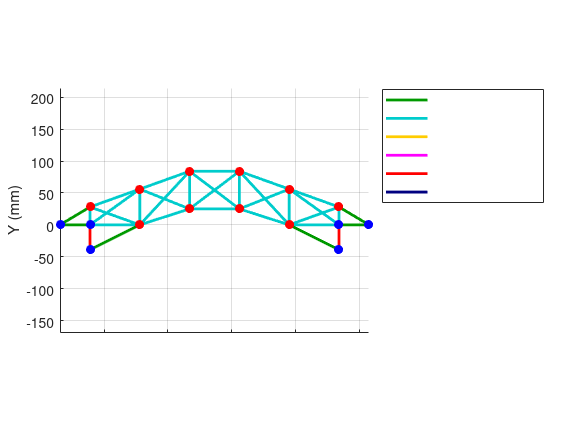


%% NOVA ETAPA: Classificação de ruptura
TR_t = 55;    % MPa tração
TR_c = 76;    % MPa compressão

status = strings(num_elementos,1);
for e = 1:num_elementos
    sigma = tensao(e);
    if sigma > TR_t
        status(e) = "rompe tração";
    elseif sigma < -TR_c
        status(e) = "rompe compressão";
    elseif sigma > 0
        status(e) = "tração segura";
    else
        status(e) = "compressão segura";
    end
end

% Detecção de "perto" do limite (>=80%)
for e = 1:num_elementos
    if status(e)=="tração segura" && tensao(e)>=0.8*TR_t
        status(e)="perto tração";
    elseif status(e)=="compressão segura" && tensao(e)<=-0.8*TR_c
        status(e)="perto compressão";
    end
end

cores = containers.Map( ...
    ["tração segura","compressão segura","perto tração","perto compressão","rompe tração","rompe compressão"], ...
    {[0 0.6 0],[0 0.8 0.8],[1 0.8 0],[1 0 1],[1 0 0],[0 0 0.5]});

%% PROJETO VIRTUAL: Plot com níveis de tensão e ruptura
figure;
hold on;
axis equal;
grid on;
title('Projeto Virtual – Níveis de Tensão e Ruptura');
xlabel('X (mm)');
ylabel('Y (mm)');

% Barras coloridas conforme status
for e = 1:num_elementos
    n1 = elementos(e,1);  n2 = elementos(e,2);
    x = [nodes(n1,1) nodes(n2,1)];
    y = [nodes(n1,2) nodes(n2,2)];
    plot(x, y, 'LineWidth', 2, 'Color', cores(status(e)));
end

% Nós restritos (azul) e livres (vermelho)
nos_res = false(num_nos,1);
for j = 1:length(restricao)
    nos_res( ceil(restricao(j)/2) ) = true;
end
for i = 1:num_nos
    if nos_res(i)
        plot(nodes(i,1),nodes(i,2),'o','MarkerFaceColor','b','MarkerEdgeColor','b','MarkerSize',6);
    else
        plot(nodes(i,1),nodes(i,2),'o','MarkerFaceColor','r','MarkerEdgeColor','r','MarkerSize',6);
    end
    text(nodes(i,1),nodes(i,2),sprintf(' %d',i),'FontSize',8,'VerticalAlignment','bottom','HorizontalAlignment','right');
end

% Defina a ordem e os rótulos que quer na legenda:
ordem = { ...
    "tração segura", ...
    "compressão segura", ...
    "perto tração", ...
    "perto compressão", ...
    "rompe tração", ...
    "rompe compressão"  ...
};

% Crie handles “fantasma” para cada categoria
h_legend = gobjects(numel(ordem),1);
for k = 1:numel(ordem)
    st = ordem{k};
    % plota um ponto invisível com a cor certa
    h_legend(k) = plot(NaN, NaN, '-', ...
        'LineWidth', 2, ...
        'Color', cores(st));
end

% Agora chama legend com esses handles e os próprios rótulos
legend(h_legend, ordem, 'Location', 'bestoutside');

hold off;


% --- Anotar no gráfico e no console os elementos que rompem e sua tensão ---
rompem = find(status=="rompe tração" | status=="rompe compressão");

if isempty(rompem)
    disp('Nenhum elemento rompe sob as cargas aplicadas.');
else
    % imprimir no console
    disp('Elementos que rompem e suas tensões [MPa]:');
    for k = 1:length(rompem)
        e = rompem(k);
        fprintf('  Elemento %2d: σ = %6.2f MPa (%s)\n', e, tensao(e), status(e));
    end
end

Elementos que rompem e suas tensões [MPa]:


  Elemento 31: σ =  56.74 MPa (rompe tração)
  Elemento 34: σ =  93.73 MPa (rompe tração)
